### Задание 4.

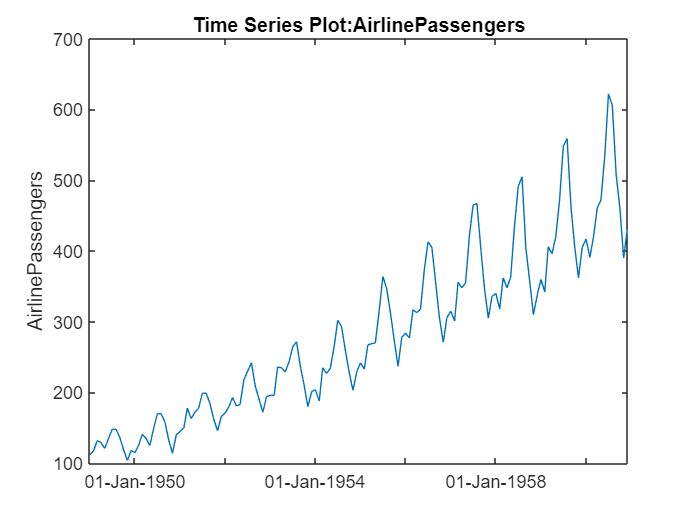

y = [112  115  145  171  196  204  242  284  315  340  360  417    % Jan
     118  126  150  180  196  188  233  277  301  318  342  391    % Feb
     132  141  178  193  236  235  267  317  356  362  406  419    % Mar
     129  135  163  181  235  227  269  313  348  348  396  461    % Apr
     121  125  172  183  229  234  270  318  355  363  420  472    % May
     135  149  178  218  243  264  315  374  422  435  472  535    % Jun
     148  170  199  230  264  302  364  413  465  491  548  622    % Jul
     148  170  199  242  272  293  347  405  467  505  559  606    % Aug
     136  158  184  209  237  259  312  355  404  404  463  508    % Sep
     119  133  162  191  211  229  274  306  347  359  407  461    % Oct
     104  114  146  172  180  203  237  271  305  310  362  390    % Nov
     118  140  166  194  201  229  278  306  336  337  405  432 ]; % Dec

yr = repmat((1949:1960),12,1);
mo = repmat((1:12)',1,12);
time = datestr(datenum(yr(:),mo(:),1));
ts = timeseries(y(:),time,'name','AirlinePassengers');
ts.TimeInfo.Format = 'dd-mmm-yyyy';
tscol = tscollection(ts);
plot(ts)

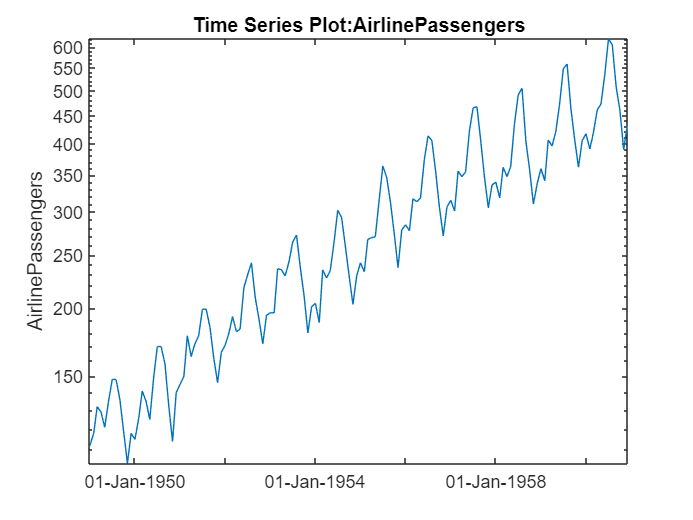

h_gca = gca;
h_gca.YScale = 'log';

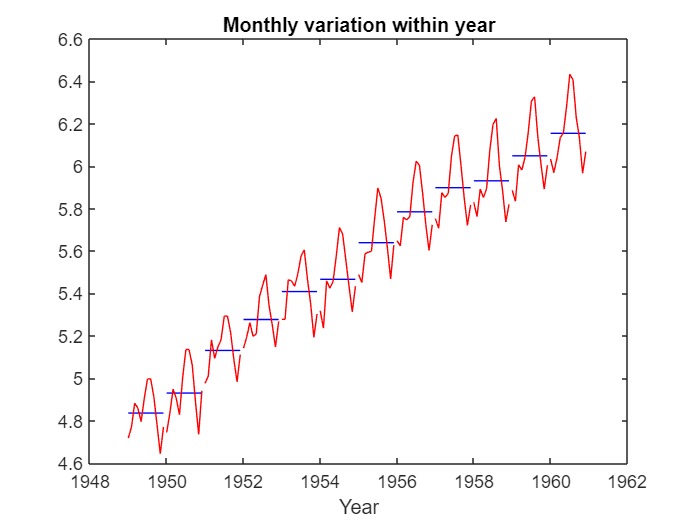

tscol = addts(tscol,log(ts.data),'logAirlinePassenger');
logts = tscol.logAirlinePassengers;

t = reshape(datenum(time),12,12);
logy = log(y);
ymean = repmat(mean(logy),12,1);
ydiff = logy - ymean;
x = yr + (mo-1)/12;
plot(x,ymean,'b-',x,ymean+ydiff,'r-')
title('Monthly variation within year')
xlabel('Year')

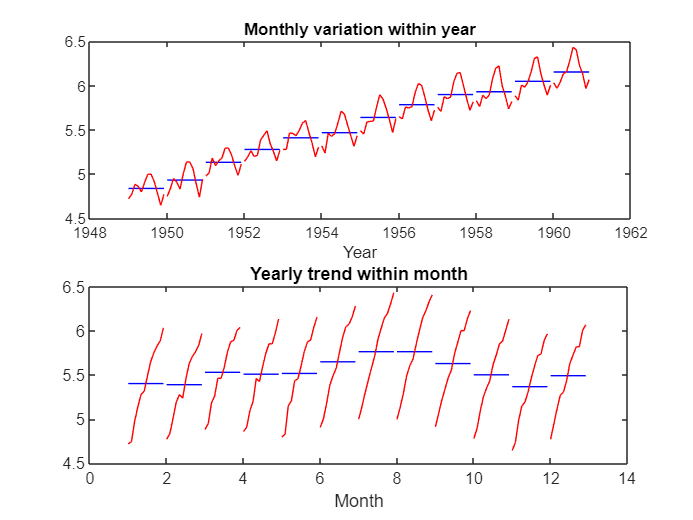

h_gca = gca;
h_gca.Position = [0.13 0.58 0.78 0.34];
subplot(2,1,2);
t = reshape(datenum(time),12,12);
mmean = repmat(mean(logy,2),1,12);
mdiff = logy - mmean;
x = mo + (yr-min(yr(:)))/12;
plot(x',mmean','b-',x',(mmean+mdiff)','r-')
title('Yearly trend within month')
xlabel('Month')

subplot(1,1,1);
X = [dummyvar(mo(:)) logts.time];
[b,bint,resid] = regress(logts.data,X);
tscol = addts(tscol,X*b,'Fit')

Time Series Collection Object: unnamed

Time vector characteristics

      Start date            01-Jan-1949
      End date              01-Dec-1960

Member Time Series Objects:

      AirlinePassengers
      logAirlinePassengers
      logAirlinePassenger
      Fit1
      Fit




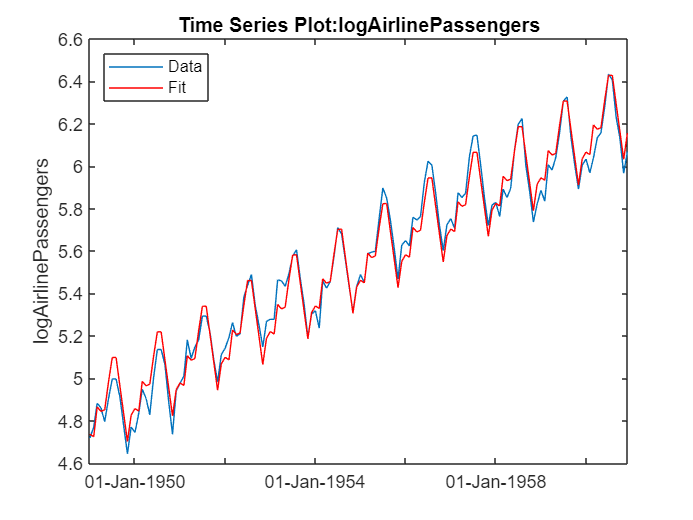

plot(logts)
hold on
plot(tscol.Fit1,'Color','r')
hold off
legend('Data','Fit','location','NW')

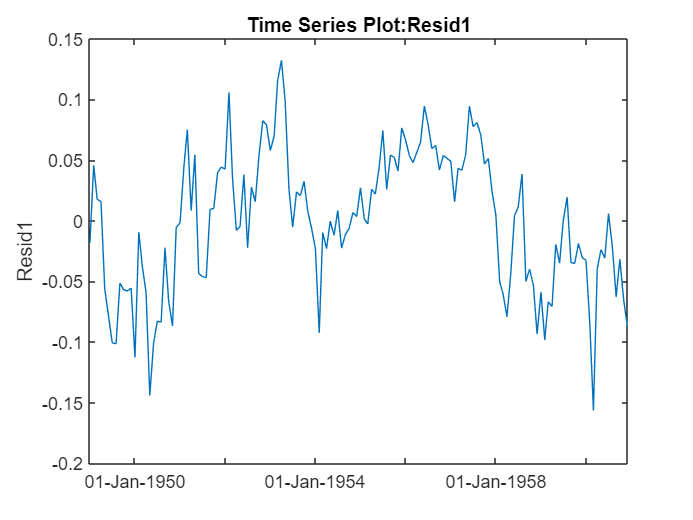

tscol = addts(tscol,resid,'Resid1');
plot(tscol.Resid1)

[p,dw] = dwtest(tscol.Resid1.data,X)

p = 7.7787e-30

dw = 0.4256

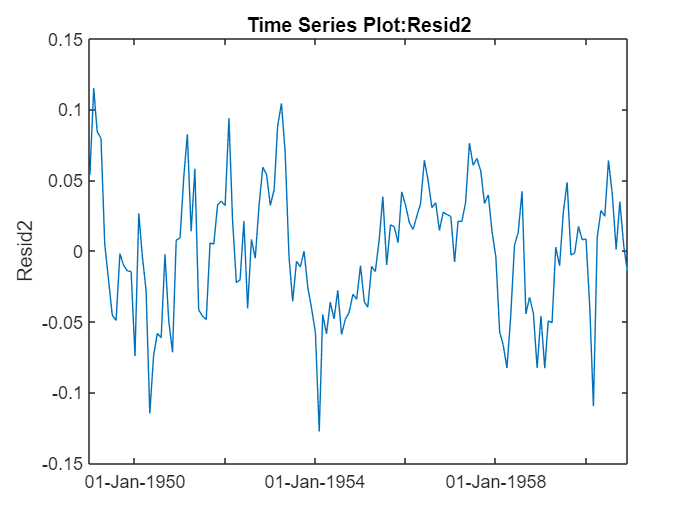

X = [dummyvar(mo(:)) logts.time logts.time.^2];
[b2,bint,resid2] = regress(logts.data,X);
tscol = addts(tscol,resid2,'Resid2');
plot(tscol.Resid2)

[p,dw] = dwtest(tscol.Resid2.data,X)

p = 8.7866e-20

dw = 0.6487

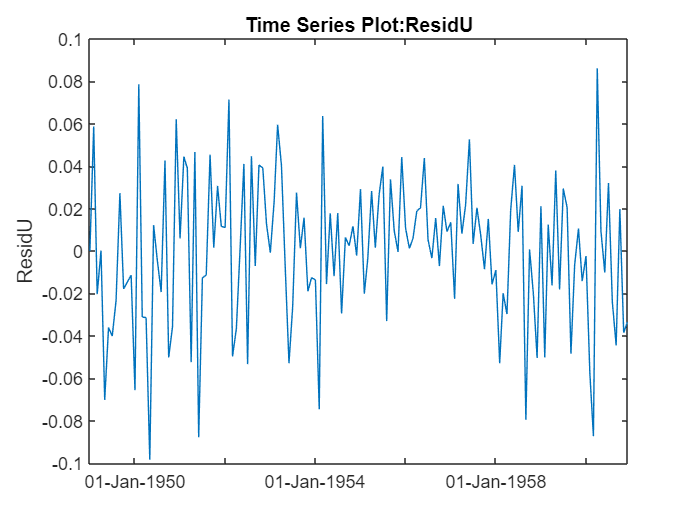

r = corr(resid(1:end-1),resid(2:end)); 
X = [dummyvar(mo(:)) logts.time];
Y = logts.data;
f = @(c,x) [Y(1); c(1)*Y(1:end-1) + (x(2:end,:)- c(1)*x(1:end-1,:))*c(2:end)];
c = nlinfit(X,Y,f,[r; b]);

u = Y - f(c,X);
tscol = addts(tscol,u,'ResidU');
plot(tscol.ResidU);

Проведем аналогичный анализ для одного из первых 366 (помесячных) временных рядов соревнования «Tourism Forecasting Part Two».

inputData = importdata('tourism2_revision2.csv');
data = inputData.data(:, 5) % выбрала пятый столбец

data =          NaN
         NaN
         NaN
         734
        1254
        1637
        1084
         988
        1051
        1129


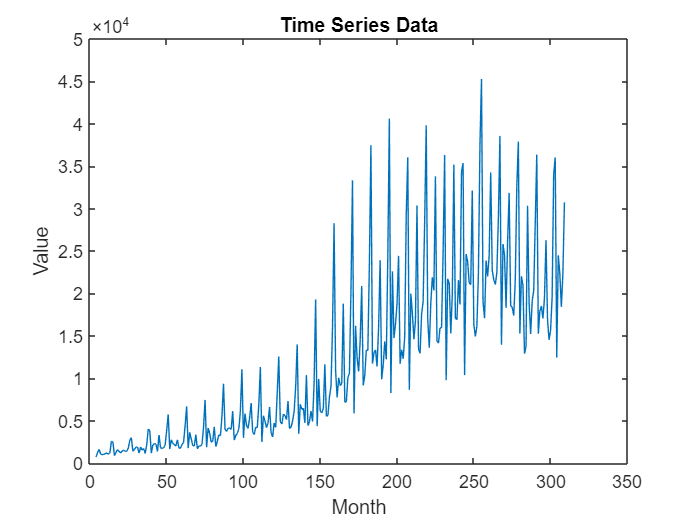


data = fillmissing(data, 'previous');

clf;
time = (1:numel(data))';

% Создание временного ряда
ts = timeseries(data, time, 'name', 'TimeSeriesData');
ts.TimeInfo.Format = 'MMM-yyyy';

% Построение графика временного ряда
figure;
plot(ts);
xlabel('Month');
ylabel('Value');
title('Time Series Data');

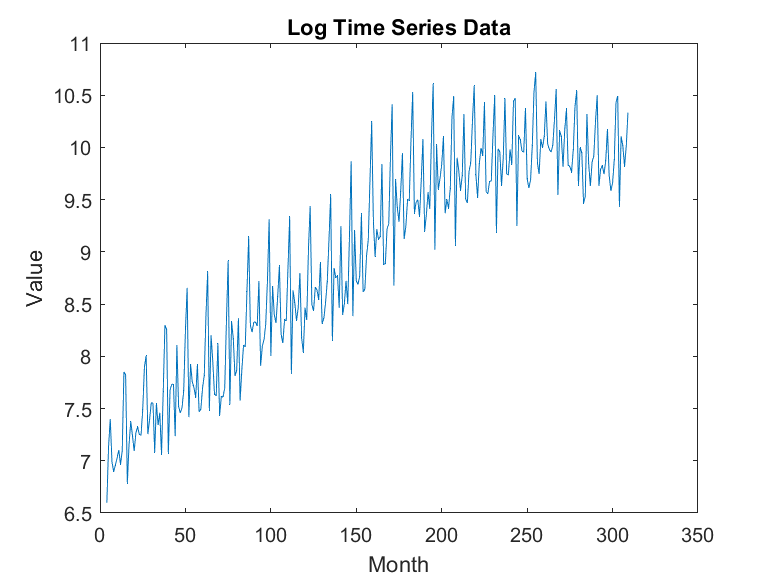

% Преобразование в логарифмическую шкалу
log_ts = log(data);
figure;
plot(log_ts);
xlabel('Month');
ylabel('Value');
title('Log Time Series Data');

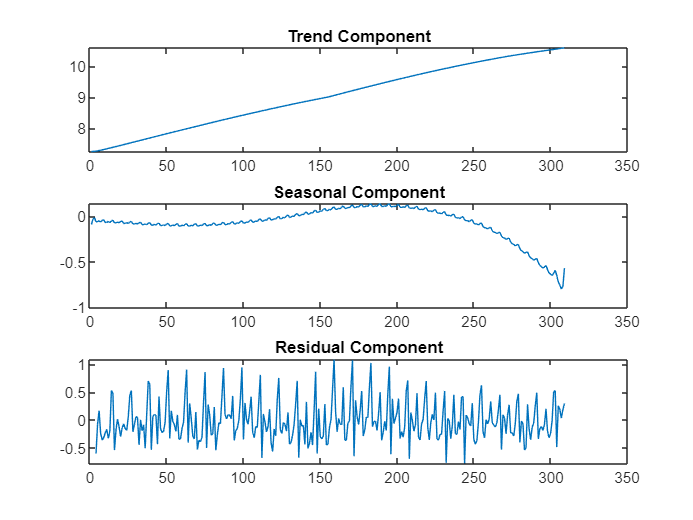

% Декомпозиция временного ряда
[LT,ST,R] = trenddecomp(log_ts);

% Визуализация результатов декомпозиции
figure;
subplot(3, 1, 1);
plot(LT);
title('Trend Component');

subplot(3, 1, 2);
plot(ST);
title('Seasonal Component');

subplot(3, 1, 3);
plot(R);
title('Residual Component');

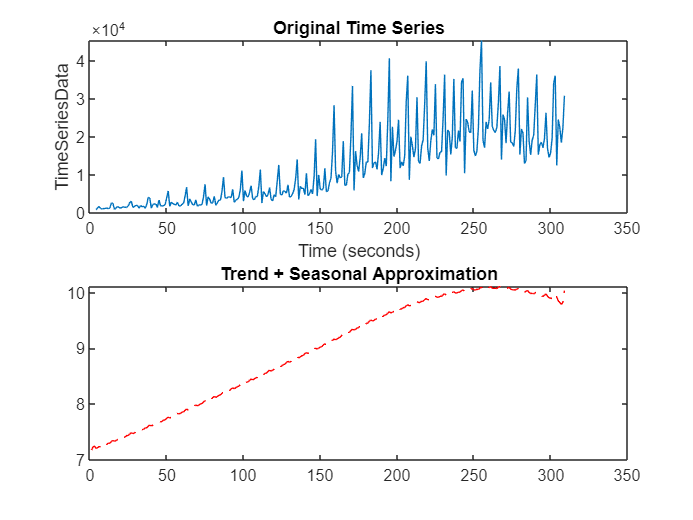


% Построение временного ряда и его аппроксимации
figure;
subplot(2, 1, 1);
plot(ts);
title('Original Time Series');

subplot(2, 1, 2);
approximation = LT + ST;
plot(time, approximation, 'r--');
title('Trend + Seasonal Approximation');

### Задание 5.

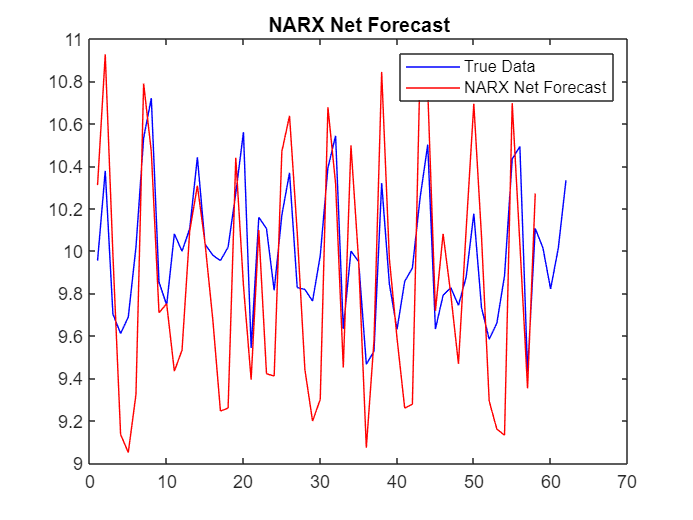

% Загрузка данных
inputData = importdata('tourism2_revision2.csv');
data = inputData.data(:, 5);

% Преобразование в логарифмическую шкалу
log_data = log(data);

% Создание временного ряда
time = (1:numel(log_data))';

% Разделение данных на обучающий и тестовый наборы
split_point = round(0.8 * length(log_data));
trainData = log_data(1:split_point);
testData = log_data(split_point+1:end);

inputDelays = 1:2;
feedbackDelays = 1:2;

net = narxnet(inputDelays, feedbackDelays, [10 10]);

inputCell = con2seq(log_data');
targetCell = con2seq(log_data');

[Xs,Xi,Ai,Ts] = preparets(net, inputCell, {}, targetCell);

% Обучение сети
net.trainParam.epochs = 100;
net.trainParam.showWindow = false;
net = train(net, Xs, Ts, Xi, Ai);

% Прогнозирование на тестовых данных
testInput = con2seq(testData(1:end-2)');
testTarget = con2seq(testData(3:end)');
[Xs_test,Xi_test,Ai_test,Ts_test] = preparets(net, testInput, {}, testTarget);
narx_net_outputs = sim(net, Xs_test, Xi_test, Ai_test);

% Отображение результатов
figure;
trueData = testData';
narxNetOutputs = cell2mat(narx_net_outputs);

plot(trueData, 'b-', 'DisplayName', 'True Data');
hold on;
plot(narxNetOutputs, 'r-', 'DisplayName', 'NARX Net Forecast');
hold off;
legend('show');
title('NARX Net Forecast');

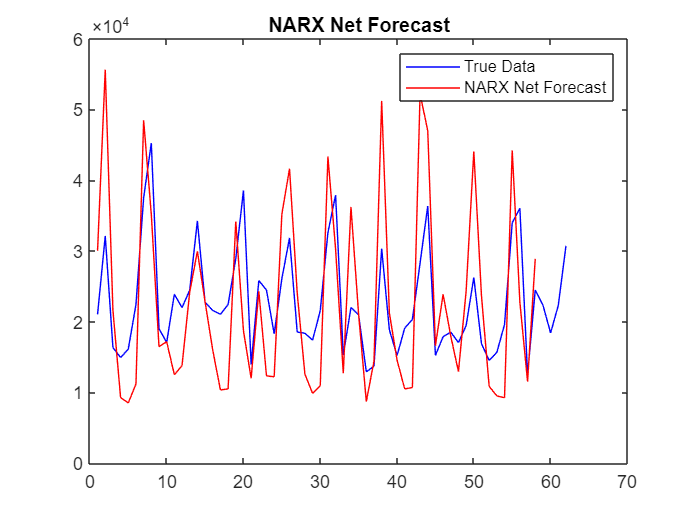

trueData_exp = exp(trueData);
narxNetOutputs_exp = exp(narxNetOutputs);

% Отображение результатов
plot(trueData_exp, 'b-', 'DisplayName', 'True Data');
hold on;
plot(narxNetOutputs_exp, 'r-', 'DisplayName', 'NARX Net Forecast');
hold off;
legend('show');
title('NARX Net Forecast');

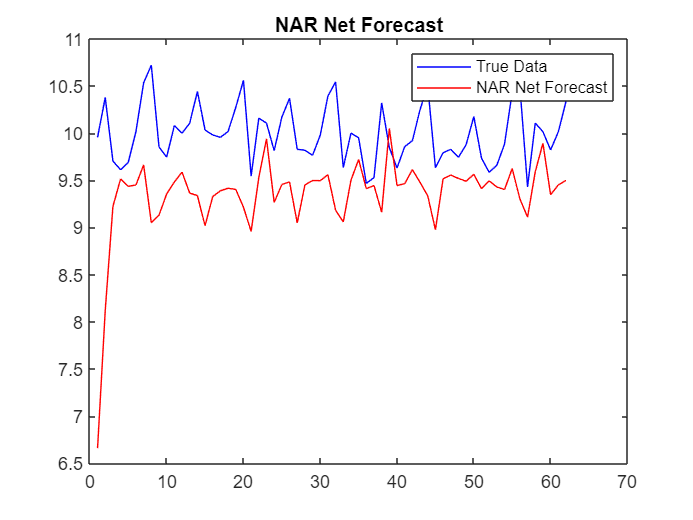

inputData = importdata('tourism2_revision2.csv');
data = inputData.data(:, 5);

log_data = log(data);

inputDelays = 1:2;
feedbackDelays = 1:2;

net = narnet(feedbackDelays, [10 10]);

inputs = con2seq(log_data');
targets = con2seq(log_data');

split_point = round(0.8 * length(log_data));
trainInputs = inputs(1:split_point);
trainTargets = targets(1:split_point);

testInputs = inputs(split_point+1:end);
testTargets = targets(split_point+1:end);

% Обучение сети
net.trainParam.epochs = 100;
net.trainParam.showWindow = false;
[net, tr] = train(net, trainInputs, trainTargets);

% Прогнозирование на тестовых данных
nar_net_outputs = sim(net, testInputs);

% Отображение результатов
figure;
trueData = cell2mat(testTargets)';
narnetOutputs = cell2mat(nar_net_outputs)';

plot(trueData, 'b-', 'DisplayName', 'True Data');
hold on;
plot(narnetOutputs, 'r-', 'DisplayName', 'NAR Net Forecast');
hold off;
legend('show');
title('NAR Net Forecast');

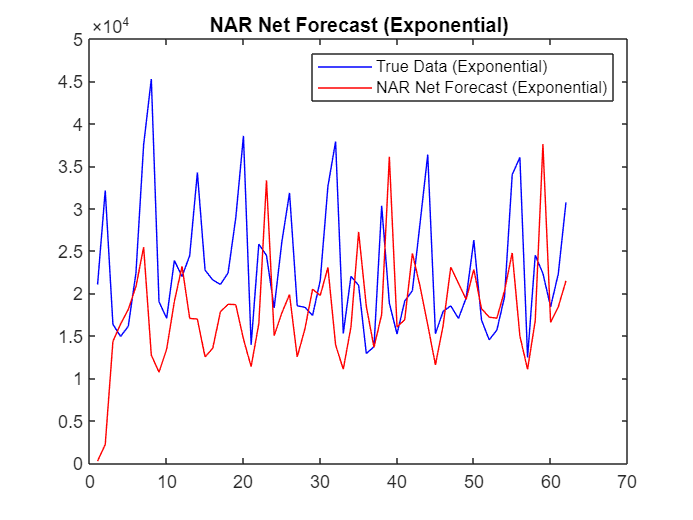

inputData = importdata('tourism2_revision2.csv');
data = inputData.data(:, 5);

log_data = log(data);

inputDelays = 1:2;
feedbackDelays = 1:2;

net = narnet(feedbackDelays, [10 10]);

inputs = con2seq(log_data');
targets = con2seq(log_data');

split_point = round(0.8 * length(log_data));
trainInputs = inputs(1:split_point);
trainTargets = targets(1:split_point);

testInputs = inputs(split_point+1:end);
testTargets = targets(split_point+1:end);

% Обучение сети
net.trainParam.epochs = 100;
net.trainParam.showWindow = false;
[net, tr] = train(net, trainInputs, trainTargets);

% Прогнозирование на тестовых данных
nar_net_outputs = sim(net, testInputs);

% Экспоненцирование исходных данных и результатов прогнозирования
trueData = exp(cell2mat(testTargets)');
narnetOutputs = exp(cell2mat(nar_net_outputs)');

% Отображение результатов
figure;
plot(trueData, 'b-', 'DisplayName', 'True Data (Exponential)');
hold on;
plot(narnetOutputs, 'r-', 'DisplayName', 'NAR Net Forecast (Exponential)');
hold off;
legend('show');
title('NAR Net Forecast (Exponential)');

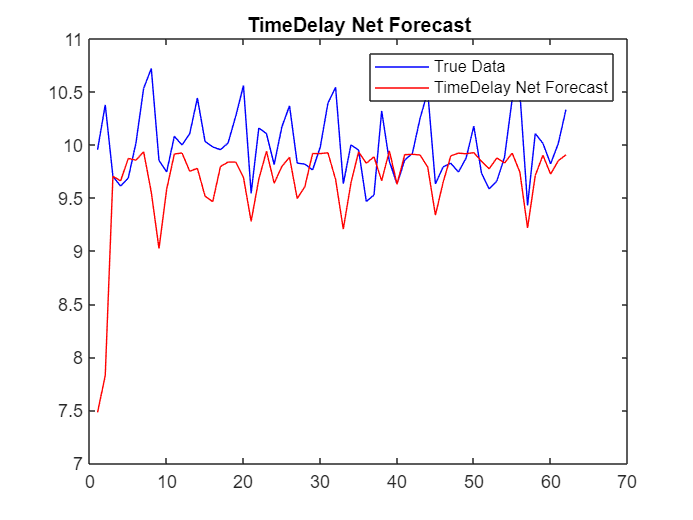

inputData = importdata('tourism2_revision2.csv');
data = inputData.data(:, 5);

log_data = log(data);

inputDelays = 1:2;
feedbackDelays = 1:2;

net = timedelaynet(inputDelays, 10);

inputs = con2seq(log_data');
targets = con2seq(log_data');

split_point = round(0.8 * length(log_data));
trainInputs = inputs(1:split_point);
trainTargets = targets(1:split_point);

testInputs = inputs(split_point+1:end);
testTargets = targets(split_point+1:end);

% Обучение сети
net.trainParam.epochs = 100;
net.trainParam.showWindow = false;
[net, tr] = train(net, trainInputs, trainTargets);

% Прогнозирование на тестовых данных
timedelay_net_outputs = sim(net, testInputs);

% Отображение результатов
figure;
trueData = cell2mat(testTargets)';
timedelayOutputs = cell2mat(timedelay_net_outputs)';

plot(trueData, 'b-', 'DisplayName', 'True Data');
hold on;
plot(timedelayOutputs, 'r-', 'DisplayName', 'TimeDelay Net Forecast');
hold off;
legend('show');
title('TimeDelay Net Forecast');

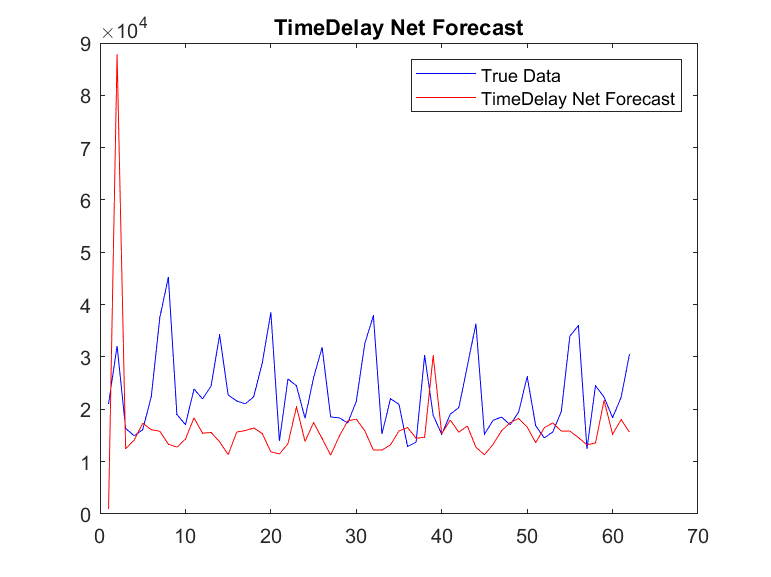

inputData = importdata('tourism2_revision2.csv');
data = inputData.data(:, 5);

log_data = log(data);

inputDelays = 1:2;
feedbackDelays = 1:2;

net = timedelaynet(inputDelays, 10);

inputs = con2seq(log_data');
targets = con2seq(log_data');

split_point = round(0.8 * length(log_data));
trainInputs = inputs(1:split_point);
trainTargets = targets(1:split_point);

testInputs = inputs(split_point+1:end);
testTargets = targets(split_point+1:end);

% Обучение сети
net.trainParam.epochs = 100;
net.trainParam.showWindow = false;
[net, tr] = train(net, trainInputs, trainTargets);

% Прогнозирование на тестовых данных
timedelay_net_outputs = sim(net, testInputs);

% Экспоненциация прогнозированных и исходных данных
timedelayOutputs = exp(cell2mat(timedelay_net_outputs)');
trueData = exp(cell2mat(testTargets)');

% Отображение результатов
figure;
plot(trueData, 'b-', 'DisplayName', 'True Data');
hold on;
plot(timedelayOutputs, 'r-', 'DisplayName', 'TimeDelay Net Forecast');
hold off;
legend('show');
title('TimeDelay Net Forecast');